# HW2_1_7

First remove all open background.

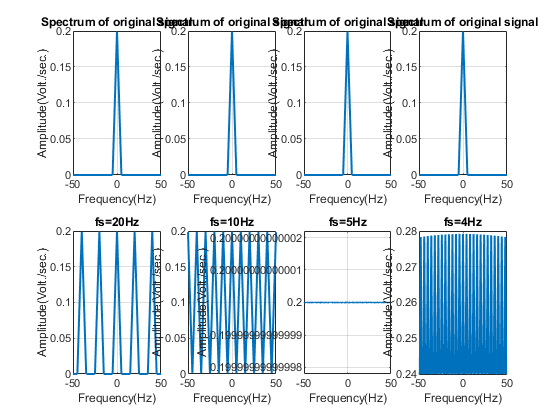

close all;
clear;
clc;
fs = 100;
Ts = 1/fs;
t = -5:Ts:5;
x = sinc(5*t).^2;
N = length(x);
sampling_frq1 = 20;
sampling_frq2 = 10;
sampling_frq3 = 5;
sampling_frq4 = 4;

f_axis = linspace(-fs / 2, fs / 2, N);

FT_x = fftshift(fft(x))/fs;
sampled_signal1 = zeros(1, N);
sampled_signal1(1:fs / sampling_frq1:end) = x(1:fs / sampling_frq1:end);
FT_sampled_signal1 = 1 / sampling_frq1 * fftshift(fft(sampled_signal1));

sampled_signal2 = zeros(1, N);
sampled_signal2(1:fs / sampling_frq2:end) = x(1:fs / sampling_frq2:end);
FT_sampled_signal2 = 1 / sampling_frq2 * fftshift(fft(sampled_signal2));

sampled_signal3 = zeros(1, N);
sampled_signal3(1:fs / sampling_frq3:end) = x(1:fs / sampling_frq3:end);
FT_sampled_signal3 = 1 / sampling_frq3 * fftshift(fft(sampled_signal3));

sampled_signal4 = zeros(1, N);
sampled_signal4(1:fs / sampling_frq4:end) = x(1:fs / sampling_frq4:end);
FT_sampled_signal4 = 1 / sampling_frq4 * fftshift(fft(sampled_signal4));
figure('Name', 'Aliasing in frequency domain');
subplot(2,4,1);
plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');

ylabel('Amplitude(Volt./sec.)');
title('Spectrum of original signal');
grid on;
subplot(2,4,2);
plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');

ylabel('Amplitude(Volt./sec.)');
title('Spectrum of original signal');
grid on;
subplot(2,4,3);
plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');

ylabel('Amplitude(Volt./sec.)');
title('Spectrum of original signal');
grid on;
subplot(2,4,4);
plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');

ylabel('Amplitude(Volt./sec.)');
title('Spectrum of original signal');
grid on;
subplot(245);
plot(f_axis, abs(FT_sampled_signal1), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');
ylabel('Amplitude(Volt./sec.)');
title('fs=20Hz');
grid on;
subplot(246);
plot(f_axis, abs(FT_sampled_signal2), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');
ylabel('Amplitude(Volt./sec.)');
title('fs=10Hz');
grid on;

subplot(247);
plot(f_axis, abs(FT_sampled_signal3), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');
ylabel('Amplitude(Volt./sec.)');
title('fs=5Hz');
grid on;

subplot(248);
plot(f_axis, abs(FT_sampled_signal4), 'LineWidth', 1.5);
xlabel('Frequency(Hz)');
ylabel('Amplitude(Volt./sec.)');
title('fs=4Hz');
grid on;

Due to sampling rate being less than Nyquist Frequnecy, aliasing happens for frequency less than 10Hz